# **Force-controlled cyclic analysis of the TUB MVLEM_3D wall**

See [MVLEM-3D | 3-D element for flexure-dominated RC walls](https://kkolozvari.github.io/MVLEM-3D/) for more details.

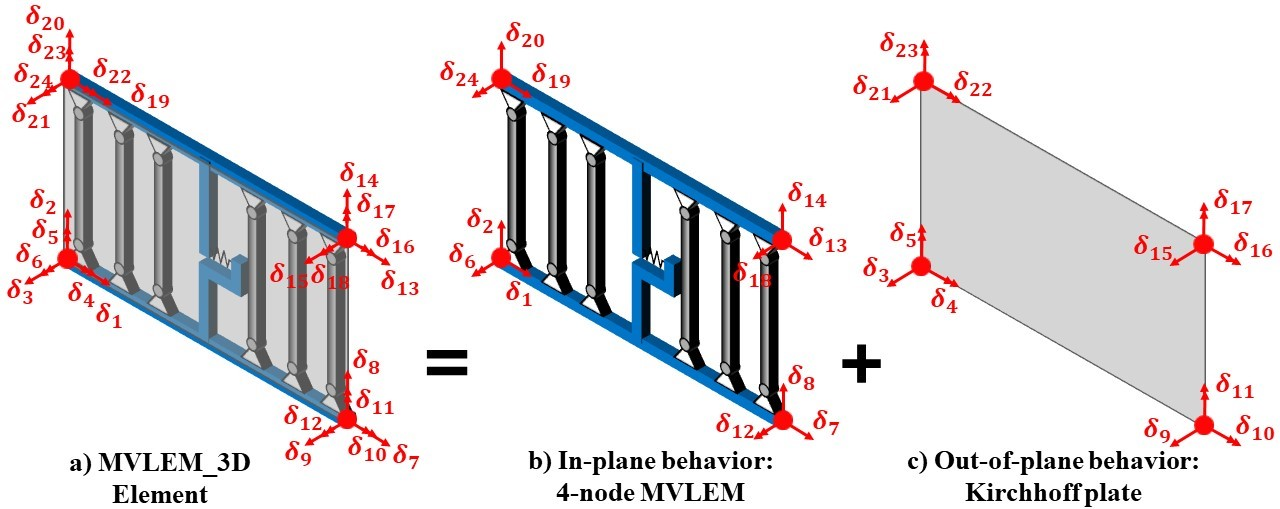

**Figure 1: MVLEM_3D element formulation**

The MVLEM_3D model (Figure 1a) is a three-dimenaional four-node element with 24 DOFs for nonlinear analysis of flexure-controlled non-rectangular reinforced concrete walls subjected to multidirectional loading. The model is an extension of the two-dimensional, two-node Multiple-Vertical-Line-Element-Model ([MVLEM](https://opensees.berkeley.edu/wiki/index.php/MVLEM_-_Multiple-Vertical-Line-Element-Model_for_RC_Walls)). The baseline MVLEM, which is essentially a line element for rectangular walls subjected to in-plane loading, is extended to a three-dimensional model formulation by: 1) applying geometric transformation of the element in-plane degrees of freedom that convert it into a four-node element formulation (Figure 1b), as well as by incorporating linear elastic out-of-plane behavior based on the Kirchhoff plate theory (Figure 1c). The in-plane and the out-of-plane element behaviors are uncoupled in the present model.

Specimen TUB (Beyer et al. 2008) is analyzed using the MVLEM_3D. Figure 2a shows the photo of the test specimen and the multidirectional displacement pattern applied at the top of the wall, while Figure 2b-c show the MVLEM_3D model of specimen TUB. **To access example files click on “View on Github” at the top of the page.**

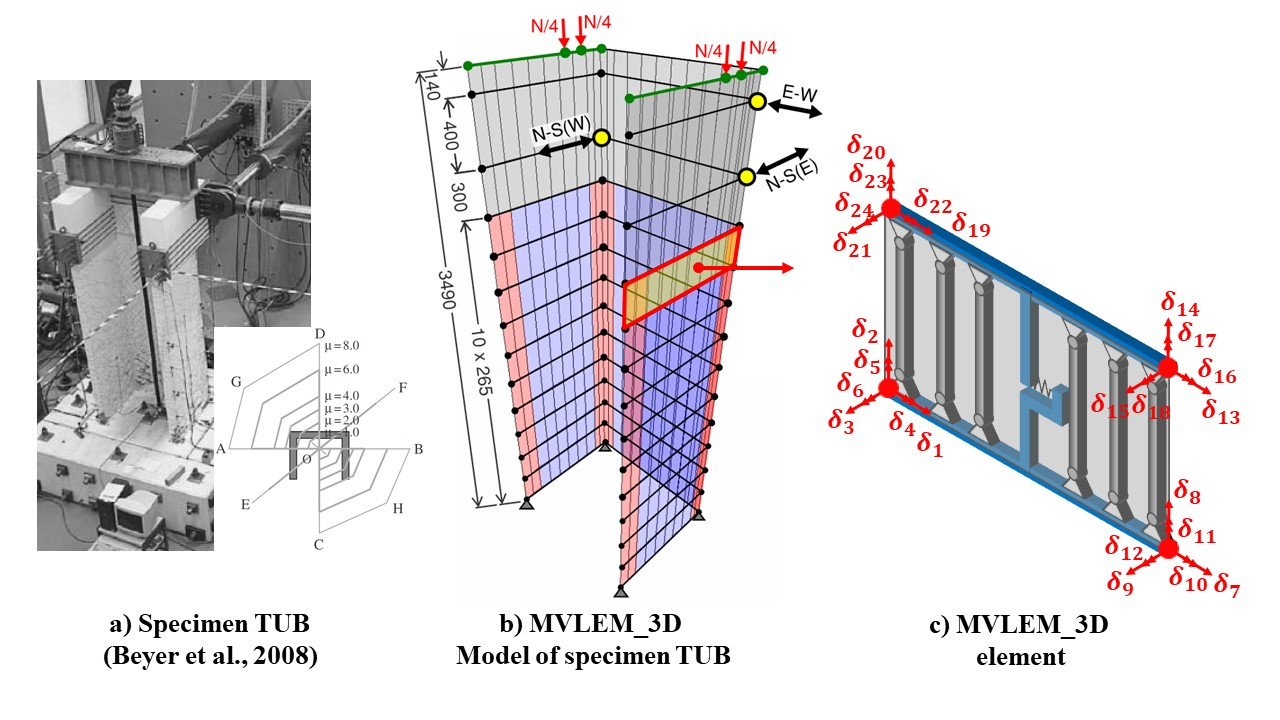

**Figure 2: MVLEM_3D model of specimen TUB**

clear; clc; close all;
runAnalysis = true;
maxSequences = 124;
showResponseViewer = true;
odbTag = "MVLEM3DForceControl";

opsmat = OpenSeesMatlab();
ops = opsmat.opensees;


### Wall model

ops.wipe();
ops.model('basic', '-ndm', 3, '-ndf', 6);

nodeData = [
 1 47.240  0.000  10.433;  2 47.240 39.370  10.433
 3 47.240 39.370  20.866;  4 47.240  0.000  20.866
 5 47.240  0.000   0.000;  6 47.240 39.370   0.000
 7 47.240 39.370  31.299;  8 47.240  0.000  31.299
 9 47.240 39.370  41.732; 10 47.240  0.000  41.732
11 47.240 39.370  52.165; 12 47.240  0.000  52.165
13 47.240 39.370  62.598; 14 47.240  0.000  62.598
15 47.240 39.370  73.031; 16 47.240  0.000  73.031
17 47.240 39.370  83.465; 18 47.240  0.000  83.465
19 47.240 39.370  93.898; 20 47.240  0.000  93.898
21 47.240 39.370 104.331; 22 47.240  0.000 104.331
23 47.240 39.370 116.142; 24 47.240  0.000 116.142
25 47.240 39.370 131.890; 26 47.240  0.000 131.890
27 47.240 39.370 137.402; 28 47.240  0.000 137.402
29  0.000  0.000  10.433; 30  0.000 39.370  10.433
31  0.000 39.370  20.866; 32  0.000  0.000  20.866
33  0.000  0.000   0.000; 34  0.000 39.370   0.000
35  0.000 39.370  31.299; 36  0.000  0.000  31.299
37  0.000 39.370  41.732; 38  0.000  0.000  41.732
39  0.000 39.370  52.165; 40  0.000  0.000  52.165
41  0.000 39.370  62.598; 42  0.000  0.000  62.598
43  0.000 39.370  73.031; 44  0.000  0.000  73.031
45  0.000 39.370  83.465; 46  0.000  0.000  83.465
47  0.000 39.370  93.898; 48  0.000  0.000  93.898
49  0.000 39.370 104.331; 50  0.000  0.000 104.331
51  0.000 39.370 116.142; 52  0.000  0.000 116.142
53  0.000 39.370 131.890; 54  0.000  0.000 131.890
55  0.000 39.370 137.402; 56  0.000  0.000 137.402
57 23.618 25.256 116.142; 58 23.618 39.370 116.142
59 23.618 39.370 131.890; 60 23.618 25.256 131.890
61  0.000 39.370 116.142; 62 47.240 39.370 116.142
63 47.240 39.370 131.890; 64  0.000 25.256 137.402
65  0.000 35.452 137.402; 66 47.240 35.452 137.402
67 47.240 25.256 137.402];
for i = 1:size(nodeData, 1)
    ops.node(nodeData(i, 1), nodeData(i, 2), nodeData(i, 3), nodeData(i, 4));
end
for tag = [34 6 5 33]
    ops.fix(tag, 1, 1, 1, 0, 0, 0);
end

% Shear, concrete and reinforcing-steel materials are taken from the TUB
% model. Force and length units are kip and inch.
kShear = 0.025;
ops.uniaxialMaterial('Elastic', 1, kShear*314705);
ops.uniaxialMaterial('Elastic', 2, kShear*377646);
ops.uniaxialMaterial('Concrete02', 201, -7.934, -0.0023, 0.0, -0.01, ...
    0.079, 0.356292015066294, 253.858060734734);
ops.uniaxialMaterial('Concrete02', 202, -9.521, -0.0029, -0.9521, -0.1, ...
    0.069, 0.356292015066294, 253.858060734734);
ops.uniaxialMaterial('SteelMPF', 301, 68.313, 68.313, 27847.246, ...
    0.0055, 0.0055, 20, 0.925, 0.15);
ops.uniaxialMaterial('SteelMPF', 302, 75.1295, 75.1295, 26831.98, ...
    0.017, 0.017, 20, 0.925, 0.15);

ops.section('ElasticMembranePlateSection', 10001, 4000, 0.2, 6, 0);

flangeCells = [
 1  1  2  3  4;  2  5  6  2  1;  3  4  3  7  8
 4  8  7  9 10;  5 10  9 11 12;  6 12 11 13 14
 7 14 13 15 16;  8 16 15 17 18;  9 18 17 19 20
10 20 19 21 22; 11 22 21 23 24; 12 24 23 25 26
13 26 25 27 28; 14 29 30 31 32; 15 33 34 30 29
16 32 31 35 36; 17 36 35 37 38; 18 38 37 39 40
19 40 39 41 42; 20 42 41 43 44; 21 44 43 45 46
22 46 45 47 48; 23 48 47 49 50; 24 50 49 51 52
25 52 51 53 54; 26 54 53 55 56];
webCells = [
27  6 34 30  2; 28  2 30 31  3; 29  3 31 35  7
30  7 35 37  9; 31  9 37 39 11; 32 11 39 41 13
33 13 41 43 15; 34 15 43 45 17; 35 17 45 47 19
36 19 47 49 21; 37 21 49 51 23; 38 23 51 53 25
39 25 53 55 27];

flangeWidth = [3.445 3.445 4.595 4.595 4.595 4.595 4.595 4.595 2.46 2.46];
flangeRho = [0.0387 0.0387 repmat(0.00342, 1, 6) 0.0226 0.0226];
flangeConcrete = [202 202 repmat(201, 1, 6) 202 202];
flangeSteel = [301 301 repmat(302, 1, 6) 301 301];
webWidth = [2.46 2.46 repmat(4.675, 1, 8) 2.46 2.46];
webRho = [0.0226 0.0226 repmat(0.003297, 1, 8) 0.0226 0.0226];
webConcrete = [202 202 repmat(201, 1, 8) 202 202];
webSteel = [301 301 repmat(302, 1, 8) 301 301];

for i = 1:size(flangeCells, 1)
    upper = any(flangeCells(i, 1) == [11:13 24:26]);
    if upper
        thick = repmat(11.81, 1, 10); rho = repmat(0.05, 1, 10);
        matC = repmat(202, 1, 10); matS = repmat(301, 1, 10);
    else
        thick = repmat(3.937, 1, 10); rho = flangeRho;
        matC = flangeConcrete; matS = flangeSteel;
    end
    addMVLEM3D(ops, flangeCells(i, :), thick, flangeWidth, rho, matC, matS, 1);
end
for i = 1:size(webCells, 1)
    upper = webCells(i, 1) >= 37;
    if upper
        thick = repmat(11.81, 1, 12); rho = repmat(0.05, 1, 12);
        matC = repmat(202, 1, 12); matS = repmat(301, 1, 12);
    else
        thick = repmat(3.937, 1, 12); rho = webRho;
        matC = webConcrete; matS = webSteel;
    end
    addMVLEM3D(ops, webCells(i, :), thick, webWidth, rho, matC, matS, 2);
end

ops.element('ShellMITC4', 40, 57, 58, 59, 60, 10001);
ops.geomTransf('Linear', 1, 0, 0, 1);
beamCells = [10006 53 59; 10007 59 25; 10008 58 23; 10009 51 58; ...
    10002 27 66; 10005 65 55; 10000 28 67; 10001 67 66; ...
    10003 56 64; 10004 64 65];
for i = 1:size(beamCells, 1)
    ops.element('elasticBeamColumn', beamCells(i, 1), beamCells(i, 2), ...
        beamCells(i, 3), 576000, 3600, 1500, 47026300, 27648000, 27648000, 1);
end

ops.uniaxialMaterial('Elastic', 601, 100000);
ops.uniaxialMaterial('Elastic', 602, 200000);
ops.equalDOF(51, 61, 1, 3, 4, 5, 6);
ops.element('zeroLength', 61, 51, 61, '-mat', 601, '-dir', 2);
ops.fix(61, 0, 1, 0, 0, 0, 0);
ops.equalDOF(23, 62, 1, 3, 4, 5, 6);
ops.element('zeroLength', 62, 23, 62, '-mat', 601, '-dir', 2);
ops.fix(62, 0, 1, 0, 0, 0, 0);
ops.equalDOF(25, 63, 2, 3, 4, 5, 6);
ops.element('zeroLength', 63, 25, 63, '-mat', 602, '-dir', 1);
ops.fix(63, 1, 0, 0, 0, 0, 0);

% Set this to true when the undeformed model should be inspected first.
% Keeping it false lets the analysis start without waiting for that window.
showUndeformedModel = true;
mvlemFiberWidths = [repmat({flangeWidth}, 26, 1); ...
    repmat({webWidth}, 13, 1)];
if showUndeformedModel
    modelViewerOpts.mvlem.internalLines.show = false;
    modelViewerOpts.mvlem.internalLines.fiberWidths = mvlemFiberWidths;
    opsmat.vis.polyscope.plotModel(opts=modelViewerOpts);
end
if ~runAnalysis
    modelData = opsmat.post.getModelData();
    fprintf('Model created: %d nodes, %d MVLEM_3D elements.\n', ...
        numel(modelData.Nodes.Tags), ...
        numel(modelData.Elements.Families.MVLEM3D.Tags));
    return;
end

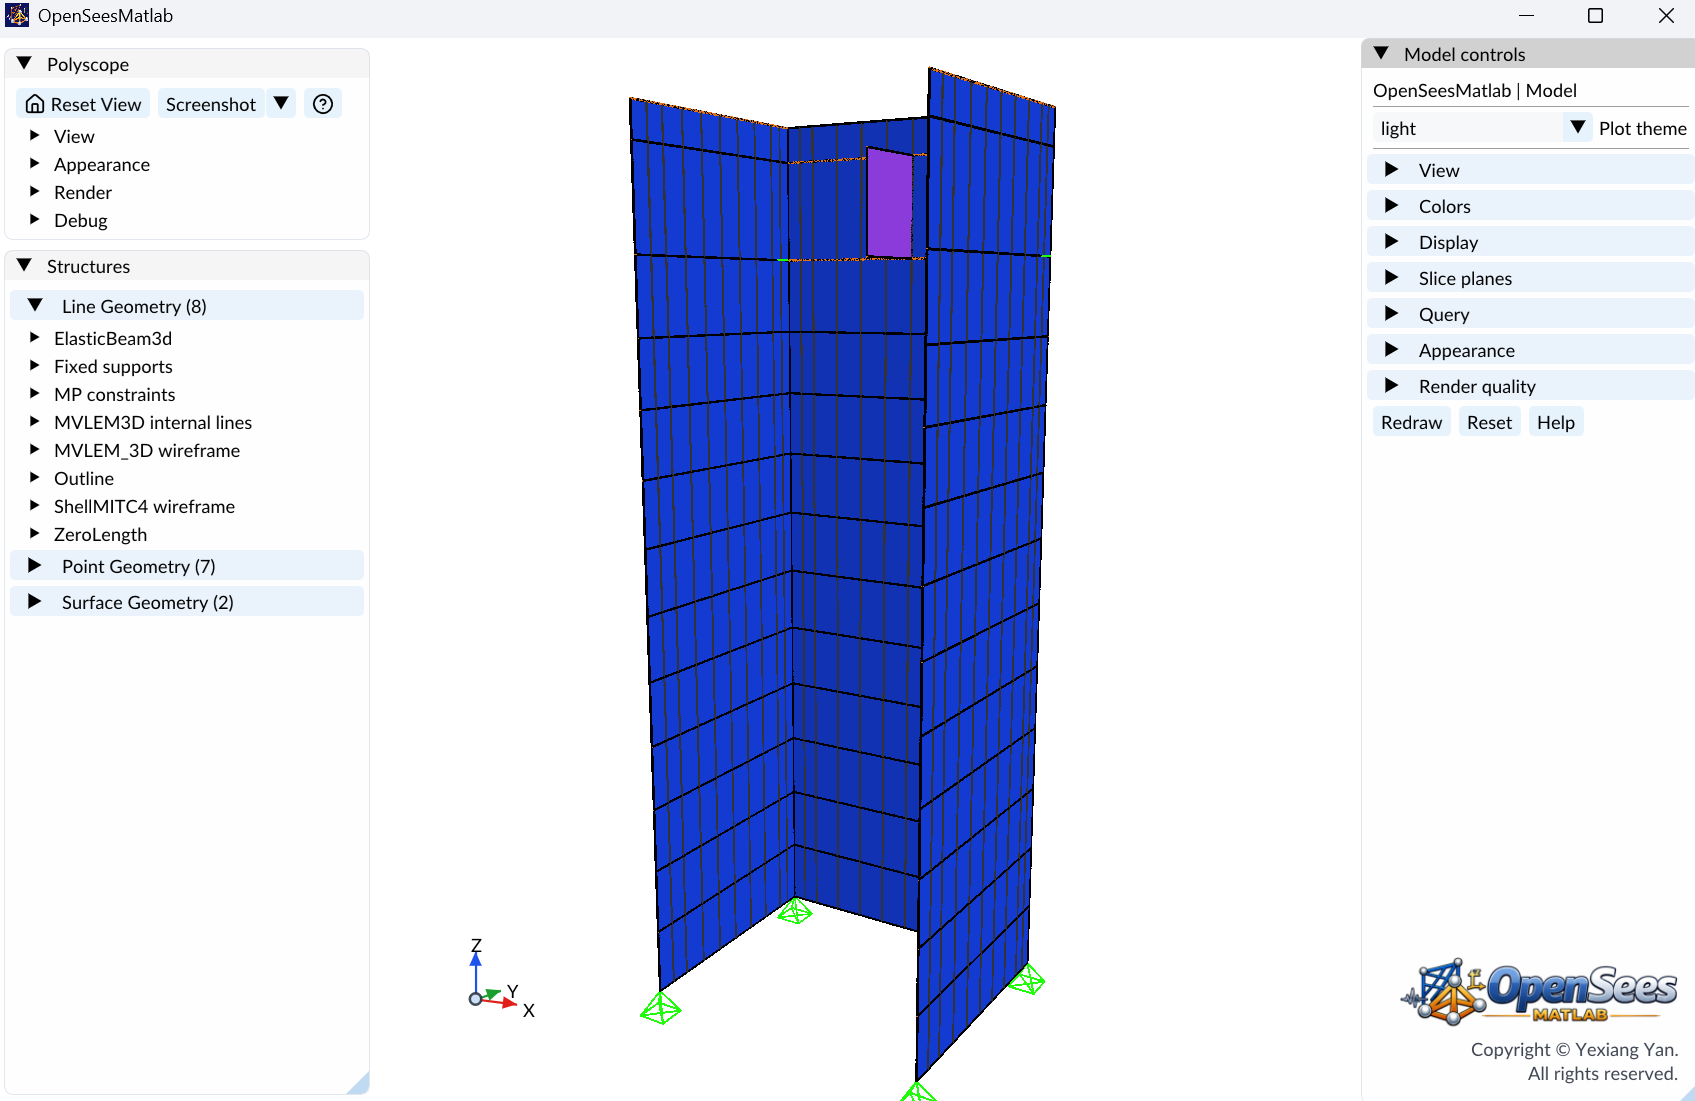

### Response database

%%
opsmat.post.createODB(odbTag, saveNodalResp=true, saveMVLEMResp=true, ...
    saveFrameResp=false, saveTrussResp=false, saveLinkResp=false, ...
    saveShellResp=false, savePlaneResp=false, saveSolidResp=false, ...
    saveContactResp=false, mvlemTags=1:39, flushEvery=20);

Output file: .openseesmatlab.output\Responses-MVLEM3DForceControl.odb\output.h5


### Gravity load

ops.timeSeries('Linear', 1);
ops.pattern('Plain', 1, 1);
for tag = 64:67
    ops.load(tag, 0, 0, -43.84, 0, 0, 0);
end

ops.system('BandGeneral');
ops.numberer('RCM');
ops.constraints('Transformation');
ops.test('NormDispIncr', 1.0e-5, 100, 0);
ops.algorithm('Newton');
ops.integrator('LoadControl', 0.01);
ops.analysis('Static');

ok = ops.analyze(100);
if ok ~= 0
    error('Gravity analysis failed.');
end
ops.loadConst('-time', 0.0);


### Lateral force history

% Each row is one force increment [Fx, Fy].
forceHistory = [
 -102991 0; 102991 0; 102442 0; -102442 0
 -102991 0; 102991 0; 102442 0; -102442 0
 0 -72016.6; 0 72016.6; 0 90085.9; 0 -90085.9
 0 -72016.6; 0 72016.6; 0 90085.9; 0 -90085.9
 103448 -73420.4; -103448 73420.4; -66084.3 49194.3; 66084.3 -49194.3
 -103448 -70893.5; 103448 70893.5; 71846.7 53225.3; -71846.7 -53225.3
 -112435 0; 112435 0; 111360 0; -111360 0
 0 -100895; 0 100895; 0 130115; 0 -130115
 -86161.1 -65779.6; 86161.1 65779.6; 85520.9 64736.7; -85520.9 -64736.7
 -112618 0; 31510.1 65458.7; 81107.6 53606.3; 0 -119065
 0 -100113; 84354.7 38765.8; 27645.6 61347.5; -112000 0
 -223886 0; 223886 0; 220822 0; -220822 0
 0 -200748; 0 200748; 0 240055; 0 -240055
 -178816 -128230; 178816 128230; 173488 123096; -173488 -123096
 -221920 0; 51586.9 119386; 170333 121071; 0 -240456
 0 -200748; 172574 81121.5; 51861.3 119627; -224435 0
 -338653 0; 338653 0; 331565 0; -331565 0
 0 -302827; 0 302827; 0 358779; 0 -358779
 -278286 -188475; 278286 188475; 258392 182157; -258392 -182157
 -337053 0; 81633.5 182619; 255419 178367; 0 -360986
 0 -303027; 271426 115816; 64941 187211; -336367 0
 -466249 0; 466249 0; 446126 0; -446126 0
 0 -398087; 0 398087; 0 485726; 0 -485726
 -364493 -253693; 364493 253693; 346199 239855; -346199 -239855
 -450013 0; 113418 244668; 336595 230830; 0 -475498
 0 -404504; 358776 150010; 97640.1 254495; -456416 0
 -680965 0; 680965 0; 661758 0; -661758 0
 0 -602445; 0 602445; 0 715553; 0 -715553
 -544224 -376428; 544224 376428; 524330 362790; -524330 -362790
 -688740 0; 183390 368005; 505350 347348; 0 -715353
 0 -604851; 545824 231833; 146803 373018; -692627 0
];

stepsPerSequence = 200;
tol = 1.0e-5;
maxNumIter = 100;
printFlag = 0;

tic;
numberOfSequences = min(size(forceHistory, 1), maxSequences);
for sequenceNum = 1:numberOfSequences
    fprintf('Sequence %d of %d.\n', sequenceNum, numberOfSequences);
    ok = runForceSequence(ops, sequenceNum, ...
        forceHistory(sequenceNum, 1), forceHistory(sequenceNum, 2), ...
        stepsPerSequence, tol, maxNumIter, printFlag);
    if ok ~= 0
        error('Pushover analysis failed at sequence %d.', sequenceNum);
    end
end

Sequence 1 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.66186 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=7.661e-07 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 2 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.68148 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=5.25757e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 3 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.67855 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=9.43282e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 4 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.66116 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=6.31633e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 5 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.63422 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=6.64801e-07 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 6 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.55305 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=3.75948e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 7 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.65334 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=7.08368e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 8 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.61948 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=3.26908e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 9 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.62772 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=1.51744e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 10 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.62446 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=5.40922e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 11 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.59096 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=5.78753e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 12 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.62525 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=3.89875e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 13 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.55514 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.17263e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 14 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.5184 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.6713e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 15 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.62719 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.78266e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 16 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.58146 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.92044e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 17 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.6749 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=2.6503e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 18 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.69863 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=7.20206e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 19 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.63695 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=3.7737e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 20 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.69423 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=1.66508e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 21 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.63649 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=2.65595e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 22 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.59594 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.27509e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 23 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.69377 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=3.60207e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 24 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.65954 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=5.42157e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 25 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.67471 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=5.62415e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 26 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.67862 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=8.35823e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 27 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.62971 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.85483e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 28 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.69367 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=8.52012e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 29 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.6117 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=3.09015e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 30 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.57128 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.47804e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 31 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.696 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.75886e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 32 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.62608 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=9.40828e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 33 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.67951 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=2.85633e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 34 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.70539 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=5.95048e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 35 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.6066 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=6.12112e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 36 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.66715 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=5.47104e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 37 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.60625 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.1245e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 38 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.56057 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=7.68012e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 39 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.6374 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=1.47042e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 40 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.61315 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=6.8999e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 41 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.65883 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=2.92221e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 42 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.66491 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=9.56738e-07 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 43 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.62833 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=2.29813e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 44 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.6819 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=6.49693e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 45 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.64254 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=2.74815e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 46 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.6043 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=6.56867e-08 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 47 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.69811 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=1.93658e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 48 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.65939 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=9.87112e-08 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 49 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.69499 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=5.09561e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 50 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.70981 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=3.14535e-07 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 51 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.63156 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=2.36607e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 52 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.68546 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=8.12943e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 53 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.67309 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=7.53639e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 54 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.60144 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=8.08348e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 55 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.70108 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.6931e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 56 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.71915 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=4 | norm=1.06342e-07 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 57 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.71354 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=3.99994e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 58 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.67992 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=1.68619e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 59 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.64913 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=3.09862e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 60 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.7127 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=6.49396e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 61 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.64115 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=3.30402e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 62 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.57506 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=6.97895e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 63 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.68269 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=6.05957e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 64 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.69316 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=1.27971e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 65 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.73146 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=2.24977e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 66 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.73008 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=7.62706e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 67 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.69246 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=2.04158e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 68 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.73873 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=8.18927e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 69 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.67314 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=2.76211e-07 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 70 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.64678 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=4.3583e-08 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 71 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.68738 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=1.78719e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 72 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.65079 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=7.99095e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 73 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.73128 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=8.38268e-08 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 74 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.73294 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=8.80805e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 75 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.69482 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=6.32217e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 76 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.74277 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=5.0716e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 77 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.6502 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=1.8361e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 78 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.57077 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=2.39258e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 79 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.69812 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=3.25104e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 80 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.64202 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.36536e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 81 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.67738 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=8.83518e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 82 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.72109 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.03781e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 83 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.65562 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=3.86799e-07 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 84 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.74516 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=6.07179e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 85 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.70019 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=5.82397e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 86 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.63539 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=6.1316e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 87 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.77244 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.93417e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 88 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.72617 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=6.39095e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 89 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.77587 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=2.79127e-07 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 90 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.81035 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=2.55015e-08 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 91 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.68084 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=3.78726e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 92 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.75975 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.50419e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 93 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.73753 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=7.64404e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 94 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.71186 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=7.0548e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 95 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.77004 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=6.86933e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 96 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.74602 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.1631e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 97 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.78325 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=3.77775e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 98 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.74613 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.46252e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 99 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.69454 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=1.40531e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 100 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.74812 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.08628e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 101 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.72318 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=2.40569e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 102 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.66151 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=1.69688e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 103 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.76568 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=5.63271e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 104 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.70491 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=5.27845e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 105 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.77912 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=7.82774e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 106 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.7706 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=8.36967e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 107 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.70738 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=8.74262e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 108 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.76286 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=8.03541e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 109 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.72591 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=2.81907e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 110 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.69128 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=3.42556e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 111 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.70362 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=8.74647e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 112 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.67611 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=7.16918e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 113 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.84195 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=8.45257e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 114 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.80174 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=4 | norm=4.26276e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 115 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.71775 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=6.49078e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 116 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.79903 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=9.85097e-08 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 117 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.75397 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=3 | norm=1.71142e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 118 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.63351 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.68879e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 119 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.71302 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=4 | norm=4.43221e-07 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 120 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.66277 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=7.14697e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 121 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.76579 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=5.03407e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 122 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.79485 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=4.4602e-06 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 123 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.72322 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=4 | norm=1.9855e-07 | KrylovNewton / NormDispIncr | analyze code=0


Sequence 124 of 124.


[OpenSees] adaptiveAnalyze:: 🎉 SUCCESS | outer steps=200/200 | attempts=200 | accepted substeps=200 | subdivisions=0 | elapsed=1.79844 s
[OpenSees] adaptiveAnalyze:: 📌 overall final | code=0 | last increment=0.005 | iterations=2 | norm=7.02868e-06 | KrylovNewton / NormDispIncr | analyze code=0


fprintf('Analysis completed in %.1f s.\n', toc);

Analysis completed in 210.2 s.


% Close and flush the HDF5 recorder before reading the response database.
ops.remove('recorders');

### MVLEM response viewer

#### Nodal responses

nodeResp = opsmat.post.getNodalResponse(odbTag);
if showResponseViewer
    opsmat.vis.polyscope.plotNodalResponse(nodeResp);
end

#### 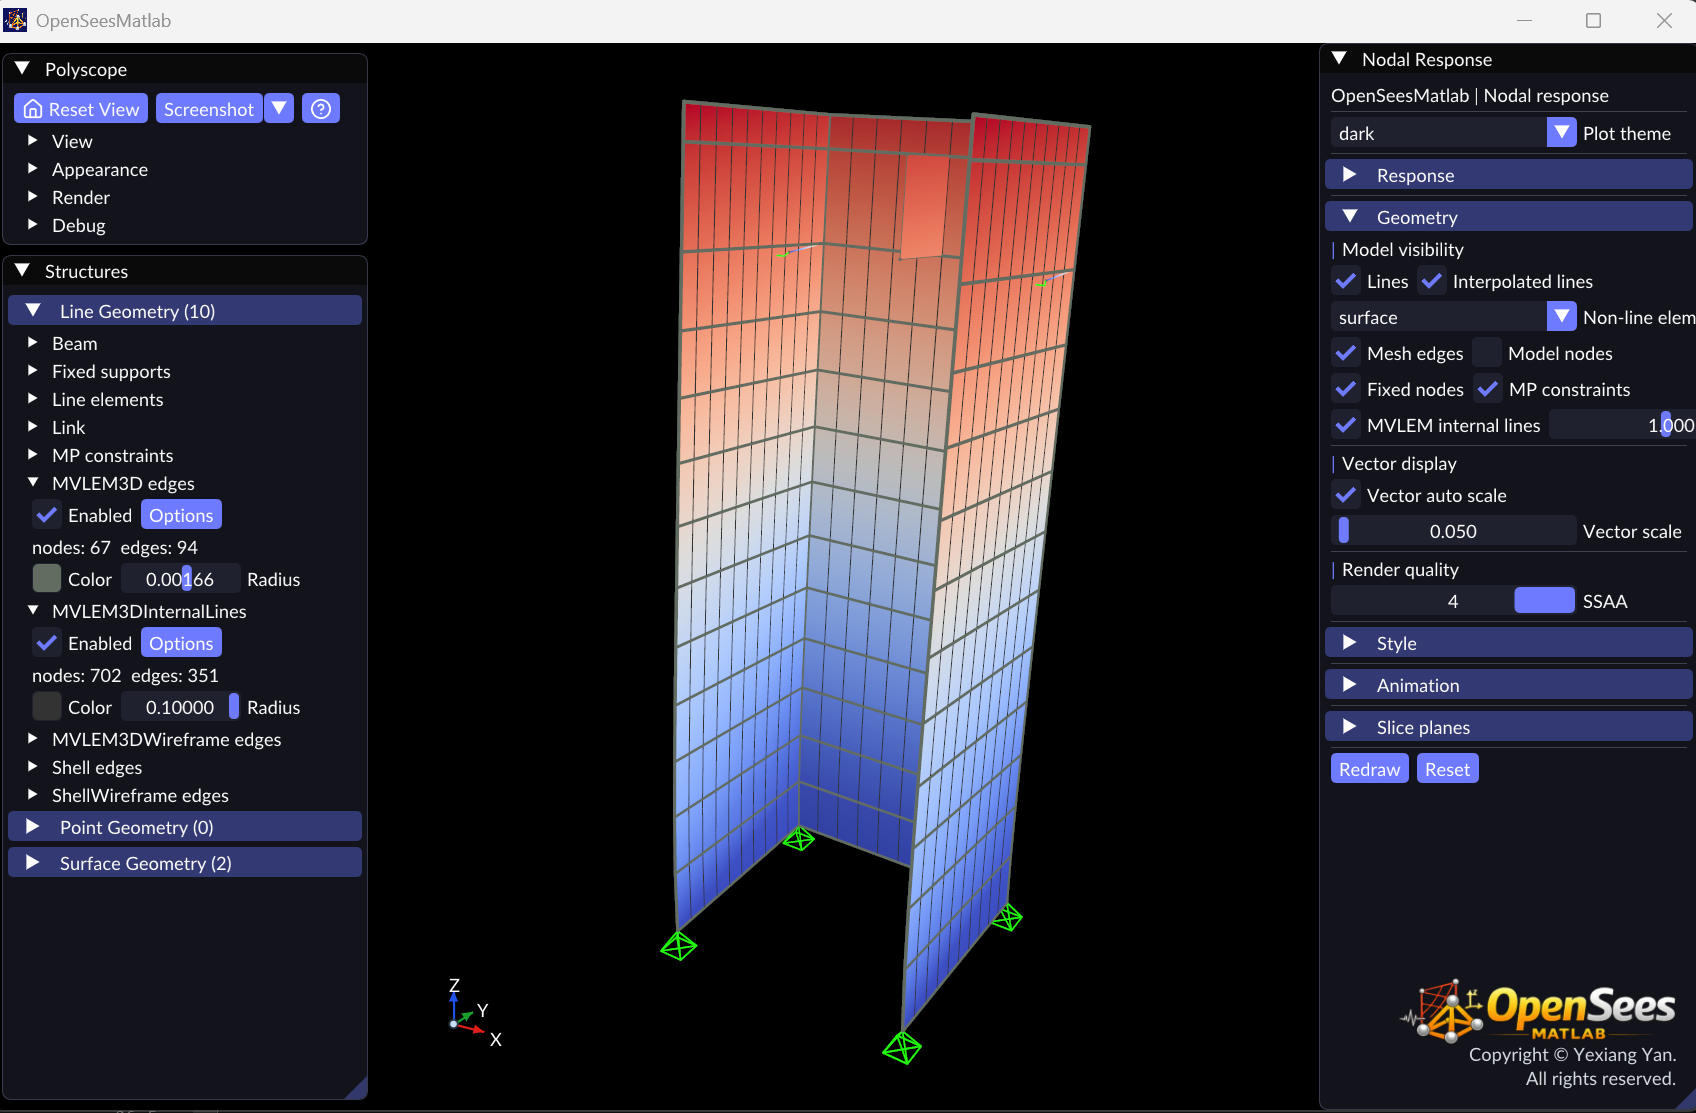

#### Element responses


mvlemResp = opsmat.post.getElementResponse(odbTag, eleType="MVLEM");
if ~exist('mvlemFiberWidths', 'var')
    % Keep this section runnable on its own after an existing ODB is loaded.
    flangeFiberWidth = [3.445 3.445 repmat(4.595, 1, 6) 2.46 2.46];
    webFiberWidth = [2.46 2.46 repmat(4.675, 1, 8) 2.46 2.46];
    mvlemFiberWidths = [repmat({flangeFiberWidth}, 26, 1); ...
        repmat({webFiberWidth}, 13, 1)];
end
viewerOpts.fibers.fiberWidths = mvlemFiberWidths;
viewerOpts.fibers.gapFraction = 0.0;
if showResponseViewer
    opsmat.vis.polyscope.plotMVLEMResponse(mvlemResp, opts=viewerOpts);
end

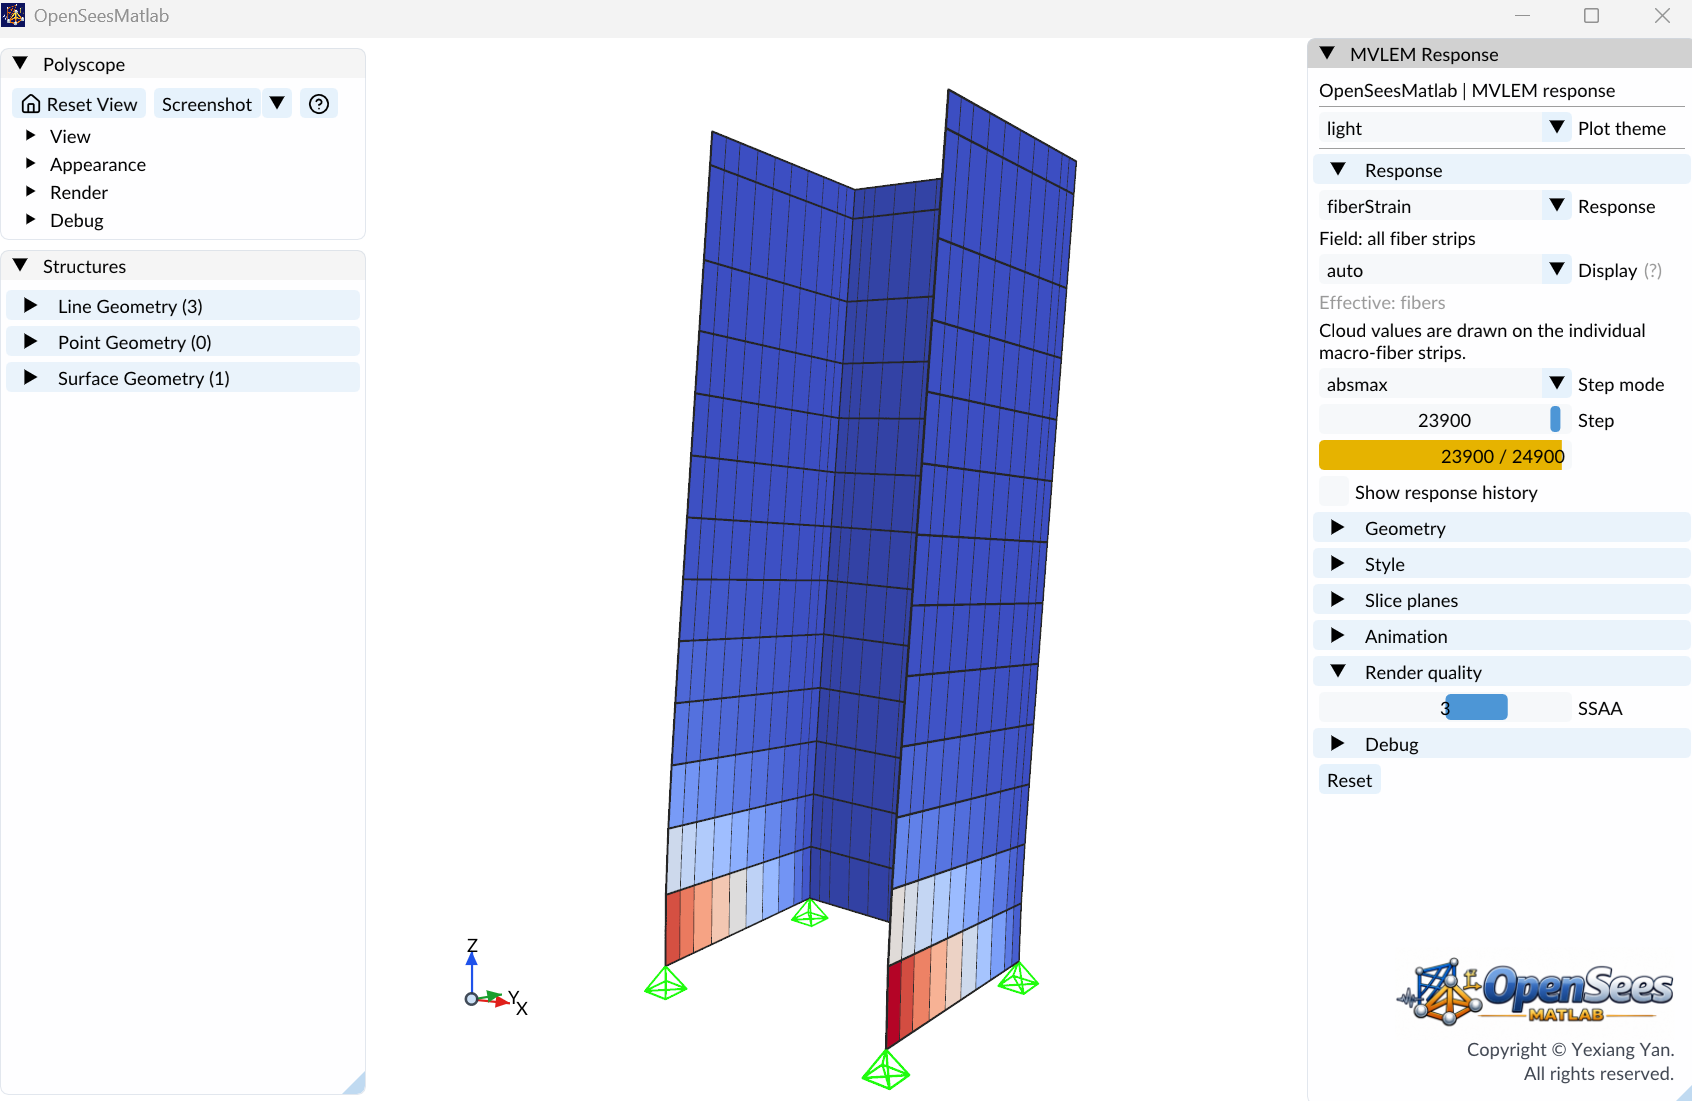

### Load-displacement hysteresis from the ODB

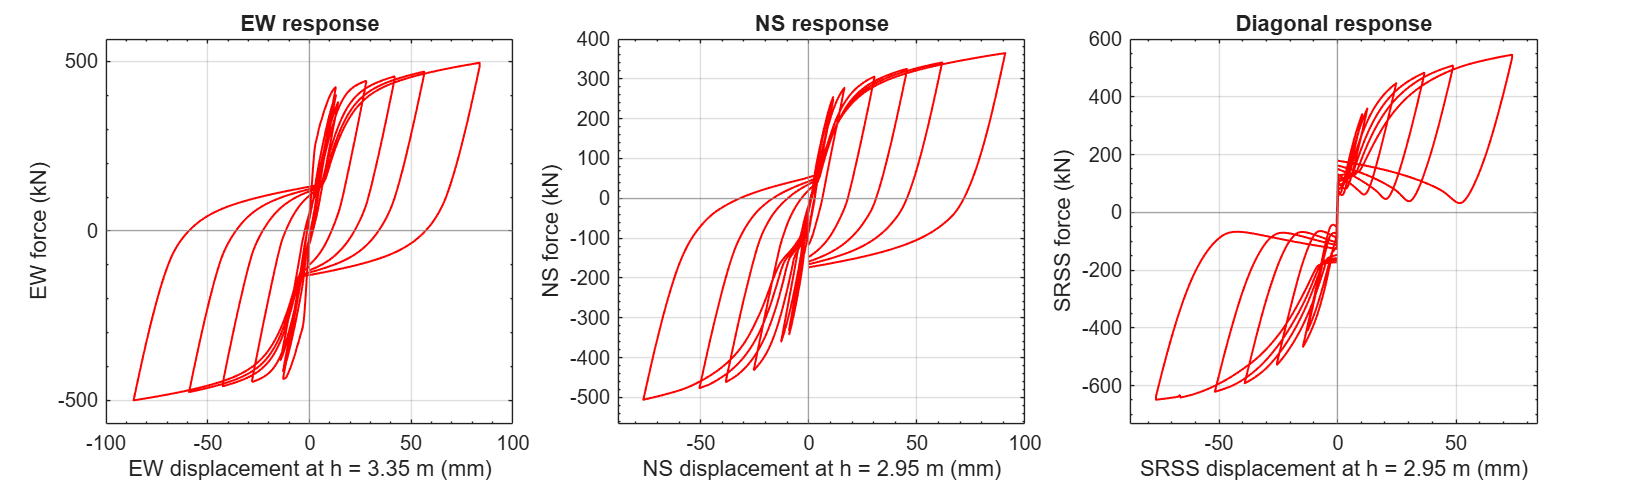

historyResp = opsmat.post.transformResponseStruct(nodeResp);
sequence = odbSequenceIndex(historyResp.time);
if ~any(sequence)
    warning('No lateral-load sequence was found in the ODB.');
else
    control3350 = odbNodalComponent(historyResp, 'disp', 'ux', 60);
    control2950 = odbNodalComponent(historyResp, 'disp', {'ux','uy'}, 57);
    baseReaction = odbNodalComponent(historyResp, 'reaction', ...
        {'ux','uy'}, [5 6 33 34]);
    forceX = -sum(baseReaction(:, :, 1), 2, 'omitnan');
    forceY = -sum(baseReaction(:, :, 2), 2, 'omitnan');

    % Reactions at the fixed ends of the loading springs identify the
    % applied X and Y force increments without using the input load table.
    actuatorX = odbNodalComponent(historyResp, 'reaction', 'ux', 63);
    actuatorY = odbNodalComponent(historyResp, 'reaction', 'uy', [61 62]);
    direction = odbLoadingDirections(sequence, -actuatorX(:, 1), ...
        -sum(actuatorY(:, :, 1), 2, 'omitnan'));
    ewRows = ismember(sequence, find(direction == 1));
    nsRows = ismember(sequence, find(direction == 2));
    diagonalRows = ismember(sequence, find(direction == 3));

    ux2950 = control2950(:, 1, 1);
    uy2950 = control2950(:, 1, 2);
    diagonalSign = sign(uy2950 + (uy2950 == 0).*ux2950);
    diagonalDisp = hypot(ux2950, uy2950).*diagonalSign;
    diagonalForce = hypot(forceX, forceY).*diagonalSign;
    mm = 25.4;
    kN = 1/0.224808943871;

    figure('Name', 'TUB MVLEM_3D hysteresis', ...
        'Position', [100 100 1200 360], 'Color', 'w');
    layout = tiledlayout(1, 3, 'TileSpacing', 'compact', ...
        'Padding', 'compact');
    plotHysteresisTile(nexttile(layout), ...
        maskedHistory(control3350(:, 1, 1), ewRows, mm), ...
        maskedHistory(forceX, ewRows, kN), ...
        'EW displacement at h = 3.35 m (mm)', 'EW force (kN)', ...
        'EW response');
    plotHysteresisTile(nexttile(layout), ...
        maskedHistory(uy2950, nsRows, mm), ...
        maskedHistory(forceY, nsRows, kN), ...
        'NS displacement at h = 2.95 m (mm)', 'NS force (kN)', ...
        'NS response');
    plotHysteresisTile(nexttile(layout), ...
        maskedHistory(diagonalDisp, diagonalRows, mm), ...
        maskedHistory(diagonalForce, diagonalRows, kN), ...
        'SRSS displacement at h = 2.95 m (mm)', 'SRSS force (kN)', ...
        'Diagonal response');
end

### Local functions

function ok = runForceSequence(ops, sequenceNum, phX, phY, ...
        stepsPerSequence, tol, maxNumIter, printFlag)
% Apply one force increment using adaptive convergence recovery.

ops.loadConst('-time', 0.0);

patternTag = sequenceNum + 1;
ops.timeSeries('Linear', patternTag);
ops.pattern('Plain', patternTag, patternTag);
ops.load(51, 0, 0.5*phY, 0, 0, 0, 0);
ops.load(23, 0, 0.5*phY, 0, 0, 0, 0);
ops.load(25, phX, 0, 0, 0, 0, 0);

ops.wipeAnalysis();
ops.constraints('Transformation');
ops.numberer('RCM');
ops.system('BandGeneral');
ops.test('NormDispIncr', tol, maxNumIter, printFlag);
ops.algorithm('KrylovNewton');
ops.integrator('LoadControl', 1.0/stepsPerSequence);
ops.analysis('Static');

fallbackAlgorithms = { ...
    {'Newton'}, ...
    {'Newton', '-initial'}, ...
    {'NewtonLineSearch'}};
fallbackTests = { ...
    {'EnergyIncr', tol, 1000, printFlag}, ...
    {'NormUnbalance', tol, 1000, printFlag}};

baseStep = 1.0/stepsPerSequence;
ok = ops.adaptiveAnalyze(stepsPerSequence, ...
    '-iterations', 5.0, 1000, ...
    '-algorithms', fallbackAlgorithms, ...
    '-tests', fallbackTests, ...
    '-subdivision', 0.5, baseStep*1.0e-6, 16, ...
    '-limits', 2000);
end

function addMVLEM3D(ops, row, thick, width, rho, matConcrete, matSteel, matShear)
% Add one MVLEM_3D panel from a connectivity row [tag I J K L].

m = numel(width);
args = [{'MVLEM_3D'}, num2cell(row), {m, '-thick'}, num2cell(thick), ...
    {'-width'}, num2cell(width), {'-rho'}, num2cell(rho), ...
    {'-matConcrete'}, num2cell(matConcrete), {'-matSteel'}, num2cell(matSteel), ...
    {'-matShear', matShear}];
ops.element(args{:});
end

function values = odbNodalComponent(resp, responseName, componentNames, nodeTags)
% Return an nStep-by-nNode-by-nComponent array from a nodal ODB response.

if ischar(componentNames) || isstring(componentNames)
    componentNames = cellstr(componentNames);
end
recordedTags = double(resp.nodeTags(:));
[found, columns] = ismember(double(nodeTags(:)), recordedTags);
if ~all(found)
    error('ODB response does not contain node tag(s): %s.', ...
        strjoin(string(nodeTags(~found)), ', '));
end
if ~isfield(resp, responseName) || ~isstruct(resp.(responseName))
    error('ODB response field "%s" was not recorded.', responseName);
end
nStep = numel(resp.time);
values = nan(nStep, numel(nodeTags), numel(componentNames));
for i = 1:numel(componentNames)
    component = componentNames{i};
    if ~isfield(resp.(responseName), component)
        error('ODB response field "%s.%s" was not recorded.', ...
            responseName, component);
    end
    data = double(resp.(responseName).(component));
    values(:, :, i) = data(:, columns);
end
end

function sequence = odbSequenceIndex(time)
% Number lateral-load sequences from recorder time resets.

time = double(time(:));
tol = 100*eps(max(1, max(abs(time), [], 'omitnan')));
starts = find(diff(time) < -tol) + 1;
sequence = zeros(size(time));
for i = 1:numel(starts)
    last = numel(time);
    if i < numel(starts), last = starts(i + 1) - 1; end
    sequence(starts(i):last) = i;
end
end

function code = odbLoadingDirections(sequence, loadX, loadY)
% Identify complete four-sequence EW, NS and positive-diagonal cycles.

nSequence = max(sequence);
raw = zeros(nSequence, 1);
for i = 1:nSequence
    rows = find(sequence == i);
    baseRow = max(1, rows(1) - 1);
    dx = loadX(rows) - loadX(baseRow);
    dy = loadY(rows) - loadY(baseRow);
    px = max(abs(dx), [], 'omitnan');
    py = max(abs(dy), [], 'omitnan');
    tol = 1e-3*max([px, py, eps]);
    if px > tol && py <= tol
        raw(i) = 1;
    elseif py > tol && px <= tol
        raw(i) = 2;
    elseif px > tol && py > tol && dx(end)*dy(end) > 0
        raw(i) = 3;
    end
end
code = zeros(size(raw));
for kind = 1:3
    selected = find(raw == kind);
    breaks = [0; find(diff(selected) > 1); numel(selected)];
    for j = 1:numel(breaks) - 1
        run = selected(breaks(j) + 1:breaks(j + 1));
        keep = 4*floor(numel(run)/4);
        if keep > 0, code(run(end - keep + 1:end)) = kind; end
    end
end
end

function values = maskedHistory(values, mask, scale)
% Scale selected rows and leave NaN gaps between loading families.

values(~mask) = NaN;
values = scale*values;
end

function plotHysteresisTile(ax, displacement, force, xLabel, yLabel, plotTitle)
% Draw one numerical load-displacement history.

plot(ax, displacement, force, 'r-', 'LineWidth', 1.0);
hold(ax, 'on');
xline(ax, 0, '-', 'Color', [0.55 0.55 0.55], 'LineWidth', 0.5);
yline(ax, 0, '-', 'Color', [0.55 0.55 0.55], 'LineWidth', 0.5);
grid(ax, 'on');
box(ax, 'on');
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
xlabel(ax, xLabel);
ylabel(ax, yLabel);
title(ax, plotTitle);
axis(ax, 'padded');
end
